# matching index test/examples

## inputs

n = 200; 
addpath(genpath("/fs03/kg98/mehul/REPOS_OFFLINE/BCT"))
originalFunction = @(A) matching_ind_und(A);
comparisonFunction = @(A) matching(A);
% comparisonFunction = @(A) getMatchingIndex_bin(A);

## make dummy data

rng('default'); 

% make dummy data
temp = reshape(randperm(n^2), [n, n]) < (n*(n-1))/2;
A = (temp|temp') .* ~eye(size(temp))

A =      0     0     1     1     0     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     0     0     1     1     0     1     1     1     1     0     1     1     1     1     1     1     1     1     0     0     1     1     0     1     1     1     0     1     1     1
     0     0     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     0     1     1     1     1     0     1     1     1     0     1     1     1     0     1     1     1     1     1     1     1     1     0     1     1     0     0
     1     1     0     1     1     1     0     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     0     1     0     0     1     0     0     1     0     1     1     1     0     0     1     1     1     1     0     1     0     1     1     0     1     1     1
     1     1     1     0     1     1     1     1     1     1     0     1     0     1     0   

fprintf('simulated binary adj matrix, density %f\n', density_und(A))

simulated binary adj matrix, density 0.743970


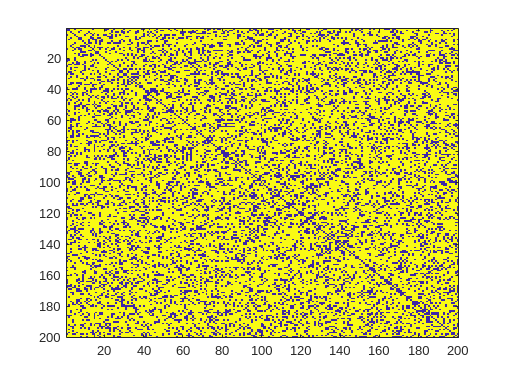

imagesc(A)


disp('simulated graph')

simulated graph


G = graph(A)

G =   graph with properties:

    Edges: [14805×2 table]
    Nodes: [200×0 table]


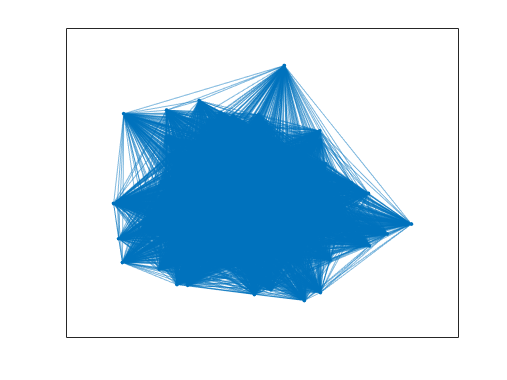

plot(G)

## using BCT

%% need to add your BCT to path
% this uses their implementation
mi1 = originalFunction(A);

## using custom function to get num and denom

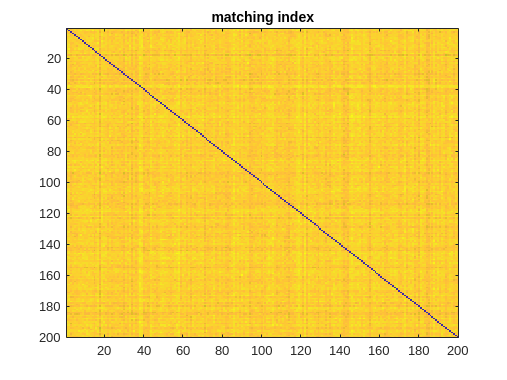

%custom function which also returns numerator and denominator
mi = comparisonFunction(A);
imagesc(mi); title('matching index');


fprintf('Are algorithms equal? %d', isequal(mi,mi1));

Are algorithms equal? 1

## compare times

tBCT =  timeit(@() originalFunction(A));
tMG = timeit(@() comparisonFunction(A));

fprintf('BCT time %f', tBCT);

BCT time 0.070372

fprintf('MG time %f', tMG);

MG time 0.002470

fprintf('MG is %f times as fast as BCT', tBCT/tMG)

MG is 28.493900 times as fast as BCT